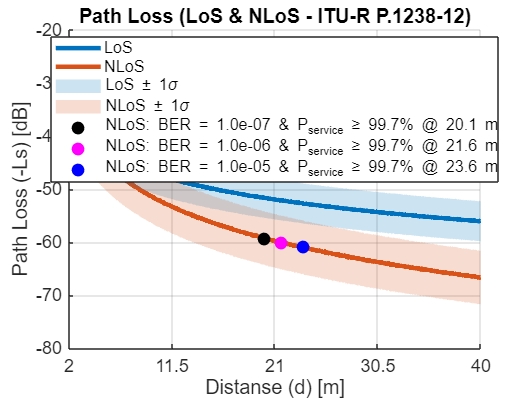

clc; clear; close all;

% Konstanter
c = 3e8;              % Lysfart (m/s)
f = 0.8e9;            % Frekvens (Hz)
lambda = c / f;       % Bølgelengde (m)

% Avstandsvektor
d = linspace(2, 40, 1000);   % Fra 2 m til 27 m

% ITU-R P.1238-12 parametere for kontor
% Line-of-Sight (LoS)
alpha_LoS = 1.46;
beta_LoS  = 34.62;
gamma_LoS = 2.03;
sigma_LoS = 3.76;  % Shadowing standardavvik (dB)

% Non-Line-of-Sight (NLoS)
alpha_NLoS = 2.46;
beta_NLoS  = 29.53;
gamma_NLoS = 2.38;
sigma_NLoS = 5.04;  % Shadowing standardavvik (dB)

% Beregn path loss (dB) for LoS og NLoS
PL_LoS = 10 * alpha_LoS * log10(d) + beta_LoS + 10 * gamma_LoS * log10(f/1e9);
PL_NLoS = 10 * alpha_NLoS * log10(d) + beta_NLoS + 10 * gamma_NLoS * log10(f/1e9);

% Generer stokastisk shadowing
num_realizations = 1e4;  % Antall realisasjoner
X_LoS = sigma_LoS * randn(num_realizations, length(d));
X_NLoS = sigma_NLoS * randn(num_realizations, length(d));

% Totalt path loss med shadowing
PL_LoS_total = PL_LoS + X_LoS;
PL_NLoS_total = PL_NLoS + X_NLoS;

% Beregn middelverdi og std
PL_LoS_mean = mean(PL_LoS_total, 1);
PL_LoS_std = std(PL_LoS_total, 1);
PL_NLoS_mean = mean(PL_NLoS_total, 1);
PL_NLoS_std = std(PL_NLoS_total, 1);

% --- Small-scale fading (Rician eller Rayleigh) ---
% Rician fading for LoS og Rayleigh fading for NLoS

% Rician fading for LoS
K_dB = 5;  % Rician K-faktor i dB
K = 10^(K_dB/10);  % Konverter til lineær skala
h_LoS = sqrt(K / (K + 1)) + (randn(num_realizations, length(d)) + 1i*randn(num_realizations, length(d))) / sqrt(2);
h_LoS_magnitude = abs(h_LoS);

% Rayleigh fading for NLoS
sigma_NLoS_fading = 1.0;  % Sett ønsket standardavvik (kan justeres)

% Generer Rayleigh fading med økt standardavvik
h_NLoS = sigma_NLoS_fading * (randn(num_realizations, length(d)) + 1i*randn(num_realizations, length(d)));
h_NLoS_magnitude = abs(h_NLoS);


% Beregn den totale fading-effekten ved å multiplisere med fading (Rician eller Rayleigh)
PL_LoS_total_fading = PL_LoS_total; % + 20*log10(h_LoS_magnitude);
PL_NLoS_total_fading = PL_NLoS_total; % + 20*log10(h_NLoS_magnitude);

% Beregn middelverdi og std etter fading
PL_LoS_mean_fading = mean(PL_LoS_total_fading, 1);
PL_LoS_std_fading = std(PL_LoS_total_fading, 1);
PL_NLoS_mean_fading = mean(PL_NLoS_total_fading, 1);
PL_NLoS_std_fading = std(PL_NLoS_total_fading, 1);

% --- Beregn sannsynlighet for mottatt signal P_service ---
% Gitte parametere
margin=0;               % margin, dB, 10 dB loss 10% av tiden
EIRP = -20.5;         % dBW (Sendereffekt)
L0 = 7;      % Systemtap (dB)
N0 = -156.2;          % Støytetthet (dBW/Hz)
Gr = 2.0;           % Mottakerantennens vinning (dBi)
Rb = 46.4;          % Bitrate (dBHz)

BER = [1e-7; 1e-6; 1e-5];  % Ønskede bitfeilrater

Eb_N0 = 10 * log10( (qfuncinv(BER)).^2 / 2 );

% Maksimalt tillatt path loss (LM)
LM = EIRP - L0 - N0 + Gr - Rb - Eb_N0 - margin;

% Beregn sannsynlighet P_service for LoS og NLoS med small-scale fading
P_service_LoS_fading = normcdf(repmat(LM, 1, length(d)), repmat(PL_LoS_mean_fading, length(LM), 1), repmat(PL_LoS_std_fading, length(LM), 1));
P_service_NLoS_fading = normcdf(repmat(LM, 1, length(d)), repmat(PL_NLoS_mean_fading, length(LM), 1), repmat(PL_NLoS_std_fading, length(LM), 1));

% --- PLOT --- 
figure;
hold on;
grid on;

% Plot middelverdiene etter small-scale fading
plot(d, -PL_LoS_mean_fading, 'LineWidth', 3, 'DisplayName', 'LoS');
plot(d, -PL_NLoS_mean_fading, 'LineWidth', 3, 'DisplayName', 'NLoS');

% Skygge rundt middelverdien (± standardavvik for LoS og NLoS etter fading)
fill([d, fliplr(d)], -[PL_LoS_mean_fading+PL_LoS_std_fading, fliplr(PL_LoS_mean_fading-PL_LoS_std_fading)], ...
     [0, 0.447, 0.741], 'FaceAlpha', 0.2, 'EdgeColor', 'none', 'DisplayName', 'LoS ± 1\sigma');
fill([d, fliplr(d)], -[PL_NLoS_mean_fading+PL_NLoS_std_fading, fliplr(PL_NLoS_mean_fading-PL_NLoS_std_fading)], ...
     [0.850, 0.325, 0.098], 'FaceAlpha', 0.2, 'EdgeColor', 'none', 'DisplayName', 'NLoS ± 1\sigma');


colors = {'black', 'magenta', 'blue'};
% Plot P_service for LoS og NLoS ved forskjellige P_target
P_target = 0.997;  
for i = 1:length(LM)
    idx_LoS = find(P_service_LoS_fading(i,:) >= P_target, 1, 'last');
    idx_NLoS = find(P_service_NLoS_fading(i,:) >= P_target, 1, 'last');
    
    if ~isempty(idx_NLoS)        
        plot(d(idx_NLoS), -PL_NLoS_mean_fading(idx_NLoS), 'ko', 'Color', colors{i}, 'MarkerFaceColor', colors{i}, 'MarkerSize', 8, ...
            'DisplayName', sprintf('NLoS: BER = %.1e & P_{service} ≥ %.1f%% @ %.1f m',BER(i), P_target*100, d(idx_NLoS)));
    end
end

% Aksetilpasning
xlabel('Distanse (d) [m]', 'FontSize', 14);
ylabel('Path Loss (-Ls) [dB]', 'FontSize', 14);
xlim([min(d),max(d)]); xticks([linspace(min(d),max(d),5)]);
title('Path Loss (LoS & NLoS - ITU-R P.1238-12)', 'FontSize', 16);
legend('Location', 'best');
set(gca, 'FontSize', 12);
hold off;